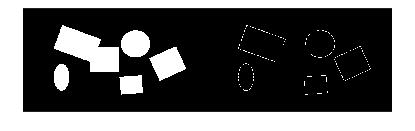

% Read in the image
img = imread("DetectingEdgesSlide.png");
[BW, image] = createMask(img);
gray = im2gray(img);
g = adapthisteq(gray);
imgFilt = imgaussfilt(g,0.2);
[imgEdges, threshOut, vertEdgeGrad, horzEdgeGrad] = edge(imgFilt , "sobel" , "nothinning");
montage({BW , imgEdges});

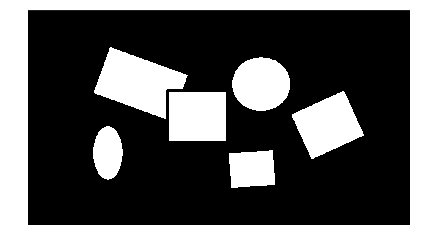

newBW = BW & (~imgEdges);
imshow(imerode(newBW,strel("disk",3)));

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 20-Jun-2022
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.890;
channel1Max = 0.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.708;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Invert mask
BW = ~BW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
